**E3DSB Opgaver 4**

**Opgave 4.2**

clear all; clc; close all;

Indlæs filen four_FIR_filters.mat.

load('four_FIR_filters.mat')

Filterkoefficienter hentes

h1 = four_FIR_filters.h1;
h2 = four_FIR_filters.h2;
h3 = four_FIR_filters.h3;
h4 = four_FIR_filters.h4;

Indlæs musiknummer

[x, fs] = audioread('03 When It Comes To You_11s(1).wav'); % afspil med sound(x, fs)

a) Filtrer med h1-h4

% frekvensspektrum for oprindeligt signal
N = length(x);
N_dft = 1024;
fft0 = mag2db(abs(fft(x, N_dft)));

y1 = filter(h1, 1, x); %afspil med sound(y1, fs)
fft1 = mag2db(abs(fft(y1, N_dft)));

y2 = filter(h2, 1, x); %afspil med sound(y2, fs)
fft2 = mag2db(abs(fft(y2, N_dft)));

y3 = filter(h3, 1, x); %afspil med sound(y3, fs)
fft3 = mag2db(abs(fft(y3, N_dft)));

y4 = filter(h4, 1, x); %afspil med sound(y4, fs)
fft4 = mag2db(abs(fft(y4, N_dft)));

b) Plot input og output i samme figur

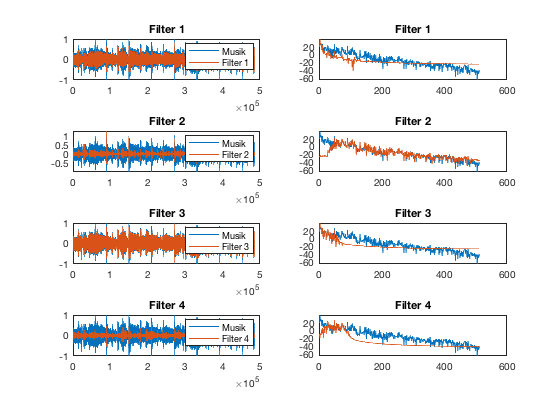

close all;

t = 'Filter 1';
subplot(4,2,1);
plot(x); hold on;
plot(y1); hold off;
title(t); legend('Musik',t);

subplot(4,2,2);
plot(fft0(1:N_dft/2)); hold on;
plot(fft1(1:N_dft/2)); hold off;
title(t);

t = 'Filter 2';
subplot(4,2,3)
plot(x); hold on;
plot(y2); hold off;
title(t); legend('Musik',t);

subplot(4,2,4);
plot(fft0(1:N_dft/2)); hold on;
plot(fft2(1:N_dft/2)); hold off;
title(t);

t = 'Filter 3';
subplot(4,2,5)
plot(x); hold on;
plot(y3); hold off;
title(t); legend('Musik',t);

subplot(4,2,6);
plot(fft0(1:N_dft/2)); hold on;
plot(fft3(1:N_dft/2)); hold off;
title(t); 

t = 'Filter 4';
subplot(4,2,7)
plot(x); hold on;
plot(y4); hold off;
title(t); legend('Musik',t);

subplot(4,2,8);
plot(fft0(1:N_dft/2)); hold on;
plot(fft4(1:N_dft/2)); hold off;
title(t); 

Baseret på lytning til den filtrerede musik, og de plottede amplitudespektra, konkluderes det, at:

- Filter 1: Lavpas.

- Filter 2: Højpas.

- Filter 3: Lavpas.

- Filter 4: Båndpas - frasorterer de laveste frekvenser og højere.